# Obstacle Avoidance

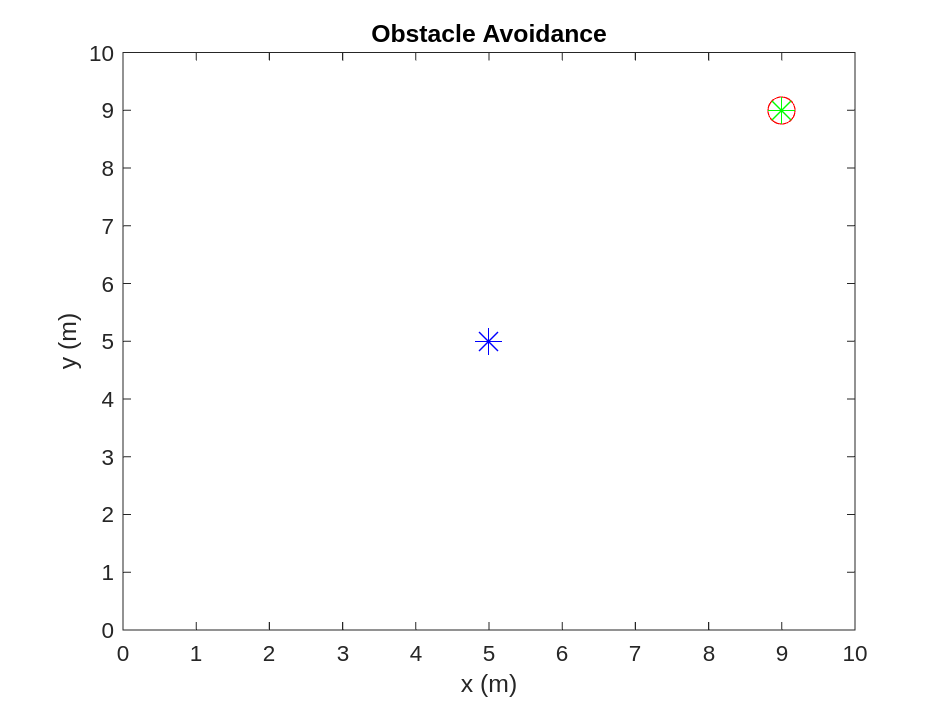

clear;clc;close;

p_ob = [5;5];
p_agent = [0;0];
p_target = [9;9];

r_shill = 0.5; a_shill = 1; p_shill = 1;
ki = 1; v_max = 1; dt = 0.1;

for i = 1:300

    if norm(p_target - p_agent) > 0

        vi = ki*min(norm(p_target - p_agent), v_max)*( (p_target - p_agent)/norm(p_target - p_agent) );
    else
        vi = 0;
    end

    vs = (p_agent - p_ob)/norm(p_agent - p_ob);

    vis_shillmax = D( (norm(p_agent - p_ob)-r_shill), a_shill, p_shill );
    vis_obstacle = A(v_max, vi, vs, vis_shillmax);
    vis_tangent = TBM(vi, p_ob, p_agent);

    p_agent = p_agent + (vi + vis_obstacle + vis_tangent*0.3)*dt;

    plot(p_agent(1,1), p_agent(2,1), "ro", p_target(1,1), p_target(2,1), "g*", p_ob(1,1), p_ob(2,1), "b*",'MarkerSize', 12);

    % Configuration of Figure
    title("Obstacle Avoidance");
    xlabel("x (m)"); ylabel("y (m)");
    xlim([0 10]); xticks(0:1:10); 
    ylim([0 10]); yticks(0:1:10);
    drawnow;
    pause(1/1000);

    hold off;

    if i < 300

        clf;
    end

end

function [vis_shillamx] = D(r, a, p)

    if r <= 0

        vis_shillamx = 0;
    elseif (0 < r*p) && (r*p < a/p)

        vis_shillamx = r*p;
    else

        vis_shillamx = sqrt(2*a*r - (a^2)/(p^2) );
    end
end

function [vis_obstacle] = A(v_max, vi, vs, vis_shillmax)

    vis = norm(vs - vi);

    if vis > vis_shillmax

        vis_obstacle = min( ( vis - vis_shillmax), v_max)*( (vs - vi)/vis );
    else

        vis_obstacle = 0;
    end
end

function [tangent_obstacle] = TBM(vi, p_ob, p_agent)

    if norm(p_agent - p_ob) <= 1 || norm(p_agent - p_ob) > 2.0

        tangent_obstacle = 0;
    else

        replusive = (p_agent - p_ob)/norm(p_agent - p_ob);
        tangent = null(replusive')/norm(null(replusive'));

        angle = (vi)'*tangent;

        if acos(angle)*(180/pi) >= 90

            tangent_obstacle = -tangent;
        else

            tangent_obstacle = tangent;
        end
    end
end